,Get operating point

% run trimming.m file
run('linear_analysis/trimming.m')

Optimizing to solve for all desired dx/dt=0, x(k+1)-x(k)=0, and y=ydes.
 
(Maximum Error)  Block
 ---------------------------------------------------------
(1.86665e-03) main_to_linearize/Drone Dynamics/Actuator Dynamics/motor_resp_bot/State Space
(1.02252e-13) main_to_linearize/Drone Dynamics/Actuator Dynamics/motor_resp_bot/State Space
(1.02252e-13) 

Linearize model from rate input to rate output

mdl = 'main_to_linearize'

mdl = 'main_to_linearize'

io(1) = linio('main_to_linearize/att_control/yaw_rate', 1, 'input')


1x2 vector of Linearization IOs: 
--------------------------
1. Linearization input perturbation located at the following signal:
- Block: main_to_linearize/att_control/yaw_rate
- Port: 1
2. Linearization output measurement located at the following signal:
- Block: main_to_linearize/Drone Dynamics/w_b_comp
- Port: 3
- Signal Name: w_z


io(2) = linio('main_to_linearize/Drone Dynamics/w_b_comp', 3, 'output')


1x2 vector of Linearization IOs: 
--------------------------
1. Linearization input perturbation located at the following signal:
- Block: main_to_linearize/att_control/yaw_rate
- Port: 1
2. Linearization output measurement located at the following signal:
- Block: main_to_linearize/Drone Dynamics/w_b_comp
- Port: 3
- Signal Name: w_z


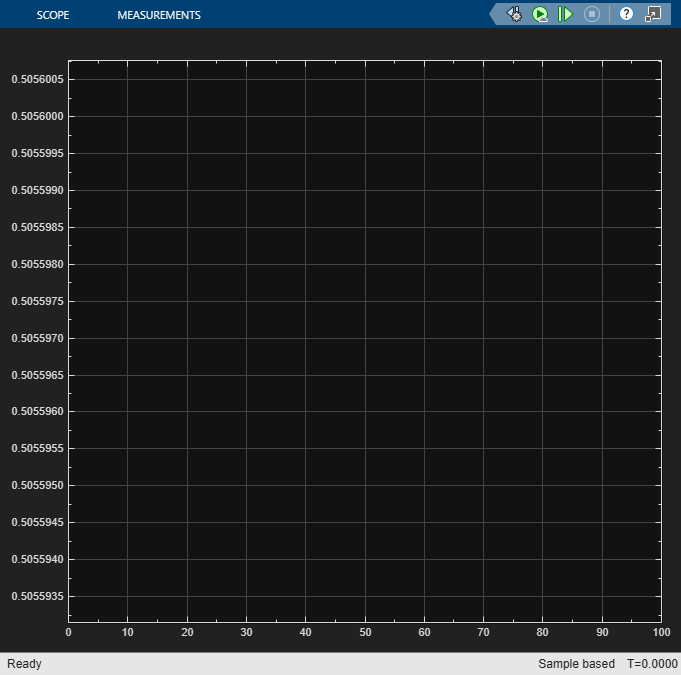

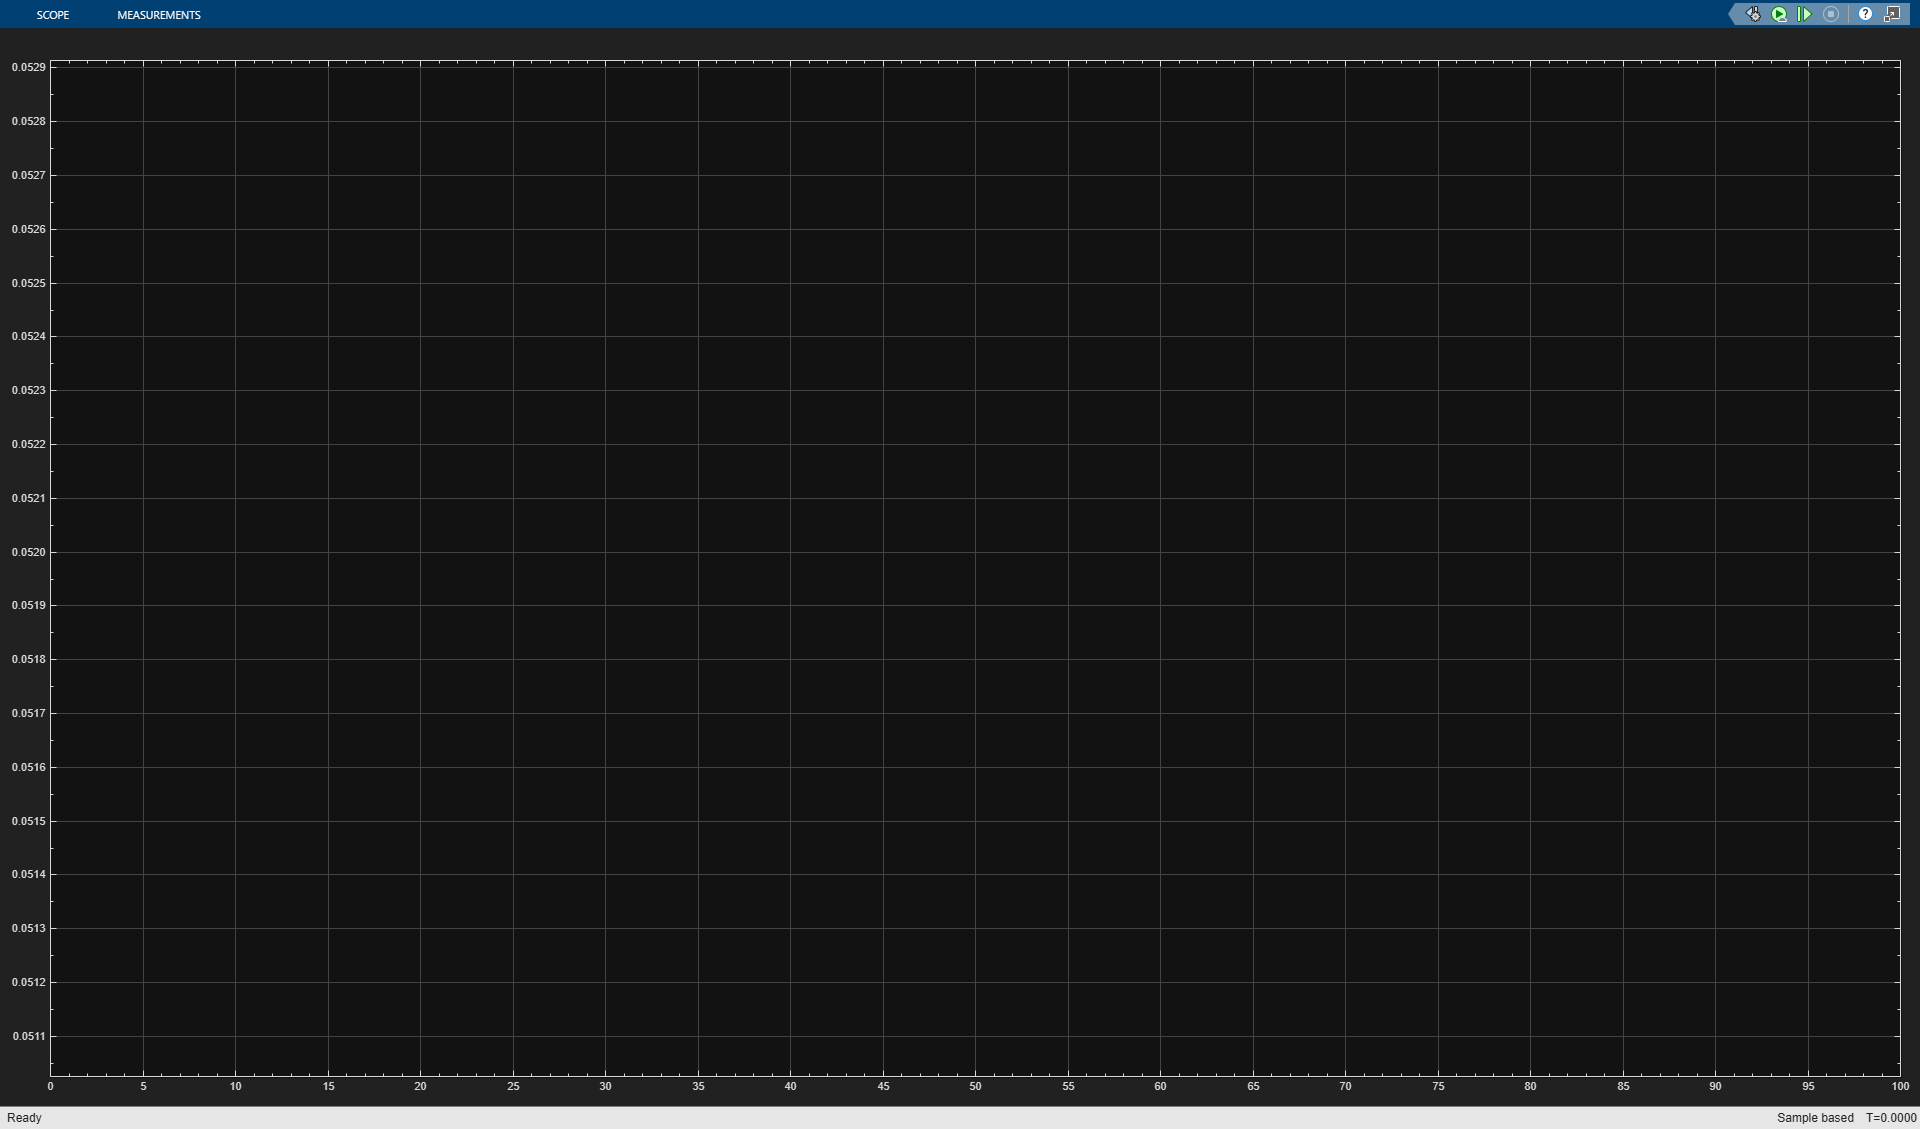


G_yaw_rate =
 
  A = 
                        p,q,r  motor_resp_b  motor_resp_b  motor_resp_t  motor_resp_t  Transport De  Transport De  Transport De  Transport De
   p,q,r                    0        -406.3    -1.322e+04         481.4     1.566e+04    -3.161e+04             0     2.668e+04             0
   motor_resp_b             0        -12.52        -59.46             0             0             0             0             0             0
   motor_resp_b             0             1             0             0             0             0             0             0             0
   motor_resp_t             0             0             0        -12.52        -59.46             0             0             0             0
   motor_resp_t             0             0             0             1             0             0             0             0             0
   Transport De             0             0             0         1.827         59.46           -60         -1200            


G_yaw_rate = linearize(mdl, io, op)

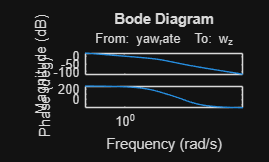

bode(G_yaw_rate)

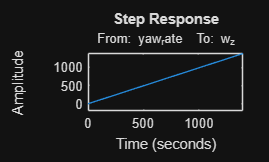

step(G_yaw_rate)

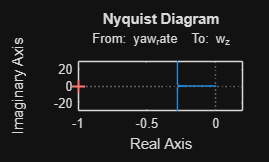

nyquist(G_yaw_rate)

% [num, den] = ss2tf(G_rate.A, G_rate.B, G_rate.C, G_rate.D)
% s = tf('s')
% G_rate_tf = tf(num, den) * exp(-0.2*s)
% [A,B,C,D] = tf2ss(G_rate_tf.Numerator{1}, G_rate_tf.Denominator{1})
% G_rate = ss(A,B,C,D) 

Control System Designer

controlSystemDesigner(G_yaw_rate)

Disk Margin Check

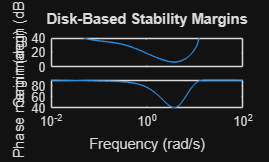

s = tf('s');
format long g;
C = (2.3528 * (s + 0.04005)) / s;

diskmarginplot(C*G_yaw_rate)

diskmargin(C*G_yaw_rate)

ans = struct with fields:
           GainMargin: [0.460485305488508 2.17162195640346]
          PhaseMargin: [-40.549248437818 40.549248437818]
           DiskMargin: 0.738815642285471
           LowerBound: 0.738815642285471
           UpperBound: 0.738815642285471
            Frequency: 3.699641359472
    WorstPerturbation: [1×1 ss]



G_cl = minreal(feedback(C * G_yaw_rate, 1))

4 states removed.

G_cl =
 
  A = 
               x1          x2          x3          x4          x5          x6
   x1       125.1       33.27      -76.82        1528       790.7      -446.5
   x2       61.07       -16.3      0.7853       95.63        57.5       39.06
   x3      -52.82        5.01       12.44      -638.2      -351.1      -50.53
   x4        1569      -116.3      -402.5   1.896e+04   1.039e+04        1105
   x5       -2909       392.4       565.1  -3.506e+04  -1.939e+04       -4207
   x6       260.5      -25.11      -60.38        3087        1697       242.2
 
  B = 
         yaw_rate
   x1  -4.683e-05
   x2   -0.002902
   x3   3.943e-08
   x4  -2.089e-05
   x5  -4.465e-05
   x6    -0.00024
 
  C = 
              x1         x2         x3         x4         x5         x6
   y1   -0.08827  -0.009827     -0.338     -1.123      2.067    -0.1507
 
  D = 
       yaw_rate
   y1         0
 
Continuous-time state-space model.


bw_rad = bandwidth(G_cl)

bw_rad =           4.78903000529635
